# 30035 Electromagnetics - Winter Exam 2024 (E24) Solutions

% Complete solutions using EM Helper Toolkit
% 
% SETUP: Run this first to add helper functions to path
addpath('C:\Users\Mads2\DTU\3.semester\Electromagnetics\Helpers')
%
% Fundamental Constants (as specified in exam):
%   c0  = 2.99792458e8 m/s
%   eps0 = 8.85418781762e-12 As/(Vm)
%   mu0  = 1.25663706144e-6 Vs/(Am)

clear; clc;

%% Physical Constants
c0   = 2.99792458e8;          % Speed of light [m/s]
eps0 = 8.85418781762e-12;     % Vacuum permittivity [F/m]
mu0  = 1.25663706144e-6;      % Vacuum permeability [H/m]
eta0 = sqrt(mu0/eps0);        % Free space impedance [~377 Ohm]

fprintf('============================================================\n');

fprintf('   30035 ELECTROMAGNETICS - WINTER EXAM 2024 (E24)\n');

   30035 ELECTROMAGNETICS - WINTER EXAM 2024 (E24)


fprintf('   Complete Solutions with EM Helper Toolkit\n');

   Complete Solutions with EM Helper Toolkit


fprintf('============================================================\n\n');

%% ========================================================================
%  PART 1: BASIC WAVE PROPERTIES (Q1-Q4)
%  ========================================================================

## Q1 - Wave Frequency from Time Plot


fprintf('=== Q1: Wave Frequency ===\n');

=== Q1: Wave Frequency ===


% From the figure: one complete cycle takes 4 ms (peak at t=0 to peak at t=4ms)
T = 4e-3;           % Period [s]
f_Q1 = 1/T;         % Frequency [Hz]

fprintf('Period from graph: T = %.0f ms\n', T*1e3);

Period from graph: T = 4 ms


fprintf('Frequency: f = 1/T = %.0f Hz\n', f_Q1);

Frequency: f = 1/T = 250 Hz


fprintf('ANSWER: 250 Hz\n\n');

ANSWER: 250 Hz



## Q2 - Phase Velocity from Two Position Measurements


fprintf('=== Q2: Phase Velocity ===\n');

=== Q2: Phase Velocity ===


% From the figure: two waves measured at positions 1 m apart
% The phase shift between them appears to be about 1 ms
delta_x = 1;        % Distance between measurements [m]
delta_t = 1e-3;     % Time shift for same phase [s] (estimated from graph)

v_p_Q2 = delta_x / delta_t;

fprintf('Distance between positions: Δx = %.0f m\n', delta_x);

Distance between positions: Δx = 1 m


fprintf('Time shift for same phase: Δt = %.1f ms\n', delta_t*1e3);

Time shift for same phase: Δt = 1.0 ms


fprintf('Phase velocity: v_p = Δx/Δt = %.0f m/s = %.0f km/s\n', v_p_Q2, v_p_Q2/1e3);

Phase velocity: v_p = Δx/Δt = 1000 m/s = 1 km/s


fprintf('ANSWER: %.0f km/s\n\n', v_p_Q2/1e3);

ANSWER: 1 km/s



## Q3 - Electrical Length from Phase Delay


fprintf('=== Q3: Electrical Length from Phase Delay ===\n');

=== Q3: Electrical Length from Phase Delay ===


% Phase delay: Δφ = π/5
% Electrical length: ℓ/λ = Δφ/(2π)
delta_phi = pi/5;
ell_over_lambda = delta_phi / (2*pi);

fprintf('Phase delay: Δφ = π/5 = %.4f rad\n', delta_phi);

Phase delay: Δφ = π/5 = 0.6283 rad


fprintf('Electrical length: ℓ/λ = Δφ/(2π) = %.2f\n', ell_over_lambda);

Electrical length: ℓ/λ = Δφ/(2π) = 0.10


fprintf('ANSWER: 0.1\n\n');

ANSWER: 0.1



## Q4 - Coaxial Cable Parameter Comparison


fprintf('=== Q4: Coaxial Cable - Which Parameter Changes? ===\n');

=== Q4: Coaxial Cable - Which Parameter Changes? ===


fprintf('For coaxial cable with same materials, same outer radius, different inner radius:\n');

For coaxial cable with same materials, same outer radius, different inner radius:


fprintf('  - Phase velocity v_p = 1/sqrt(με) → depends only on materials → SAME\n');

  - Phase velocity v_p = 1/sqrt(με) → depends only on materials → SAME


fprintf('  - Propagation constant γ = jω√(με) → depends on materials → SAME\n');

  - Propagation constant γ = jω√(με) → depends on materials → SAME


fprintf('  - Phase constant β = ω√(με) → depends on materials → SAME\n');

  - Phase constant β = ω√(με) → depends on materials → SAME


fprintf('  - Characteristic impedance Z0 = (1/2π)√(μ/ε)·ln(b/a) → depends on geometry → DIFFERENT\n');

  - Characteristic impedance Z0 = (1/2π)√(μ/ε)·ln(b/a) → depends on geometry → DIFFERENT


fprintf('ANSWER: The characteristic impedance\n\n');

ANSWER: The characteristic impedance



%% ========================================================================
%  PART 2: TRANSMISSION LINE CIRCUITS (Q5-Q15)
%  ========================================================================

## Q5 - Reflection Coefficient at Plane B (R-L Load)


fprintf('=== Q5: Reflection Coefficient at Plane B ===\n');

=== Q5: Reflection Coefficient at Plane B ===



% 1. Define Parameters from Problem Statement
f_Q5  = 100e6;      % 100 MHz
Z0_Q5 = 75;         % Line impedance
R_Q5  = 25;         % Series Resistor
L_Q5  = 200e-9;     % Series Inductor (200 nH)

% 2. Calculate Load Impedance (Series R + L)
omega_Q5 = 2 * pi * f_Q5;
Z_L_Q5   = R_Q5 + 1j * omega_Q5 * L_Q5;  % Z_total = R + jωL

fprintf('Load impedance: Z_L = %.0f + j%.2f Ω\n', real(Z_L_Q5), imag(Z_L_Q5));

Load impedance: Z_L = 25 + j125.66 Ω



% 3. Calculate Reflection Coefficient (Gamma)
r_Q5 = TLine('Gamma', Z0_Q5, Z_L_Q5);


=== Reflection Coefficient ===
  Z0 = 75.00 Ohm
  Z  = 25.0000 +125.6637j Ohm
  ------------------------------
  Gamma = 0.4184 +0.7308j
  |Gamma| = 0.8421
  angle(Gamma) = 60.21 deg
  VSWR = 11.6697




% 4. Convert to Polar for Final Answer
[mag_Gamma, ang_Gamma] = rect2pol(r_Q5.Gamma);

fprintf('ANSWER: Γ_B = %.2f ∠ %.0f°\n\n', mag_Gamma, ang_Gamma);

ANSWER: Γ_B = 0.84 ∠ 60°




%% Q6 - Reflection Coefficient at Plane A (25 Ω Load)
fprintf('=== Q6: Reflection Coefficient at Plane A ===\n');

=== Q6: Reflection Coefficient at Plane A ===


% Given: Z0 = 75 Ω, Z_L = 25 Ω, ℓ = 0.75 m, u_p = 1.5×10^7 m/s, f = 100 MHz

Z0_Q6 = 75;             % [Ω]
Z_L_Q6 = 25;            % [Ω]
ell_Q6 = 0.75;          % [m]
u_p_Q6 = 1.5e7;         % [m/s]
f_Q6 = 100e6;           % [Hz]

% Calculate wavelength and electrical length
lambda_Q6 = u_p_Q6 / f_Q6;
ell_lambda_Q6 = ell_Q6 / lambda_Q6;

fprintf('λ = u_p/f = %.2f m\n', lambda_Q6);

λ = u_p/f = 0.15 m


fprintf('ℓ/λ = %.2f/%.2f = %.1f (i.e., 5 full wavelengths)\n', ell_Q6, lambda_Q6, ell_lambda_Q6);

ℓ/λ = 0.75/0.15 = 5.0 (i.e., 5 full wavelengths)



% Using TLine for full analysis
r_Q6 = TLine(Z0_Q6, Z_L_Q6, ell_lambda_Q6);


      TRANSMISSION LINE ANALYSIS         
  Z0 = 75.00 Ohm
  ZL = 25.0000 +0.0000j Ohm
  Length = 5.0000 lambda
------------------------------------------
  Z_in = 25.0000 +0.0000j Ohm
  |Z_in| = 25.0000 Ohm
------------------------------------------
  Gamma_L = -0.5000 +0.0000j
  |Gamma_L| = 0.5000, angle = 180.00 deg
  Gamma_in = -0.5000 -0.0000j
------------------------------------------
  VSWR = 3.0000
  Return Loss = 6.02 dB
  Power delivered = 75.00%
------------------------------------------
  First V_max at 0.2500 lambda from load
  First V_min at 0.0000 lambda from load




[mag_Gamma_A, ang_Gamma_A] = rect2pol(r_Q6.Gamma_in);
fprintf('ANSWER: Γ_A = %.2f∠%.0f°\n\n', mag_Gamma_A, ang_Gamma_A);

ANSWER: Γ_A = 0.50∠-180°



## Q7 - VSWR of Short-Circuited TL


fprintf('=== Q7: VSWR of Short-Circuited TL ===\n');

=== Q7: VSWR of Short-Circuited TL ===


% Short circuit: Z_L = 0

Z0_Q7 = 50;  % Any value works
Z_L_Q7 = 0;  % Short circuit

r_Q7 = TLine('Gamma', Z0_Q7, Z_L_Q7);


=== Reflection Coefficient ===
  Z0 = 50.00 Ohm
  Z  = 0.0000 +0.0000j Ohm
  ------------------------------
  Gamma = -1.0000 +0.0000j
  |Gamma| = 1.0000
  angle(Gamma) = 180.00 deg
  VSWR = Inf




fprintf('Short circuit: Z_L = 0\n');

Short circuit: Z_L = 0


fprintf('Γ = -1, |Γ| = 1\n');

Γ = -1, |Γ| = 1


fprintf('VSWR = (1 + |Γ|)/(1 - |Γ|) = ∞\n');

VSWR = (1 + |Γ|)/(1 - |Γ|) = ∞


fprintf('ANSWER: ∞\n\n');

ANSWER: ∞



## Q8 - Load Impedance from Current Maximum and |Γ|


fprintf('=== Q8: Unknown Load from Current Maximum ===\n');

=== Q8: Unknown Load from Current Maximum ===


% Given: Z0 = 50 Ω, |Γ| = -8 dB, first current max at ℓ = 0.2λ from load

Z0_Q8 = 50;
Gamma_dB = -8;
ell_lambda_Q8 = 0.2;

% Convert Γ from dB
mag_Gamma_Q8 = 10^(Gamma_dB/20);
fprintf('|Γ| = 10^(-8/20) = %.4f\n', mag_Gamma_Q8);

|Γ| = 10^(-8/20) = 0.3981



% Current max (voltage min) at 0.2λ from load
beta_d = 2*pi*ell_lambda_Q8;
phi_L = pi + 2*beta_d;
phi_L = mod(phi_L + pi, 2*pi) - pi;  % Normalize to [-π, π]

Gamma_L_Q8 = mag_Gamma_Q8 * exp(1j*phi_L);

% Use TLine to convert Gamma to Z
r_Q8 = TLine('Z', Z0_Q8, Gamma_L_Q8);


=== Impedance from Gamma ===
  Z0 = 50.00 Ohm
  Gamma = 0.3221 -0.2340j
  |Gamma| = 0.3981, angle = -36.00 deg
  ----------------------------
  Z = 81.8052 -45.4956j Ohm




fprintf('Phase of Γ_L: %.1f°\n', rad2deg(phi_L));

Phase of Γ_L: -36.0°


fprintf('Z_L = %.1f + j%.1f Ω\n', real(r_Q8.Z), imag(r_Q8.Z));

Z_L = 81.8 + j-45.5 Ω


fprintf('ANSWER: Z_L = (81.8 - j45.5) Ω\n\n');

ANSWER: Z_L = (81.8 - j45.5) Ω



## Q9 - Input Impedance for ℓ = λ


fprintf('=== Q9: Input Impedance for ℓ = λ ===\n');

=== Q9: Input Impedance for ℓ = λ ===


% Given: Z0 = 50 Ω, Z_L = 35 Ω, ℓ = λ

Z0_Q9 = 50;
Z_L_Q9 = 35;
ell_lambda_Q9 = 1;  % One full wavelength

% Using TLine helper
r_Q9 = TLine(Z0_Q9, Z_L_Q9, ell_lambda_Q9);


      TRANSMISSION LINE ANALYSIS         
  Z0 = 50.00 Ohm
  ZL = 35.0000 +0.0000j Ohm
  Length = 1.0000 lambda
------------------------------------------
  Z_in = 35.0000 +0.0000j Ohm
  |Z_in| = 35.0000 Ohm
------------------------------------------
  Gamma_L = -0.1765 +0.0000j
  |Gamma_L| = 0.1765, angle = 180.00 deg
  Gamma_in = -0.1765 -0.0000j
------------------------------------------
  VSWR = 1.4286
  Return Loss = 15.07 dB
  Power delivered = 96.89%
------------------------------------------
  First V_max at 0.2500 lambda from load
  First V_min at 0.0000 lambda from load




fprintf('For ℓ = λ: Z_in = Z_L (line repeats)\n');

For ℓ = λ: Z_in = Z_L (line repeats)


fprintf('ANSWER: %.0f Ω\n\n', real(r_Q9.Z_in));

ANSWER: 35 Ω



## Q10 - Parallel Quarter-Wave TLs


fprintf('=== Q10: Parallel λ/4 TLs ===\n');

=== Q10: Parallel λ/4 TLs ===


% Two identical λ/4 TLs in parallel, each with Z0 and terminated with Z_L

fprintf('Each λ/4 TL transforms: Z_in_single = Z0²/Z_L\n');

Each λ/4 TL transforms: Z_in_single = Z0²/Z_L


fprintf('Two identical branches in parallel:\n');

Two identical branches in parallel:


fprintf('Z_in_total = Z_in_single/2 = Z0²/(2·Z_L)\n');

Z_in_total = Z_in_single/2 = Z0²/(2·Z_L)


fprintf('ANSWER: Z0²/(2·Z_L)\n\n');

ANSWER: Z0²/(2·Z_L)



## Q11 - Open Stub as Inductor


fprintf('=== Q11: Open Stub as Inductor ===\n');

=== Q11: Open Stub as Inductor ===


% Design open stub to act as L = 20 nH at f = 2 GHz
% Z0 = 75 Ω, u_p = 0.66·c0

L_eq = 20e-9;           % Equivalent inductance [H]
f_Q11 = 2e9;            % Frequency [Hz]
Z0_Q11 = 75;            % Characteristic impedance [Ω]
u_p_Q11 = 0.66*c0;      % Phase velocity [m/s]

omega_Q11 = 2*pi*f_Q11;
lambda_Q11 = u_p_Q11 / f_Q11;

% Target impedance (inductive)
Z_target = 1j*omega_Q11*L_eq;
fprintf('Target: Z = jωL = j%.2f Ω\n', imag(Z_target));

Target: Z = jωL = j251.33 Ω



% Using TLine stub design for open stub
r_Q11 = TLine('stub', Z_target, Z0_Q11, 'open');


         STUB DESIGN
  Target Z = j251.3274 Ohm
  Stub Z0 = 75.00 Ohm
------------------------------------------
  OPEN-CIRCUITED STUB:
    cot(βℓ) = -251.3274 / 75.00 = -3.351032
    βℓ = 2.8516 rad = 163.38°
    ℓ = 0.4538 λ  (or 0.9538 λ)
    Verify: Z_in = -j·75.00·cot(2.8516) = j251.3274 Ohm ✓
------------------------------------------




% Calculate physical length
ell_Q11 = r_Q11.open.len_lambda * lambda_Q11;

fprintf('λ = %.4f m = %.2f mm\n', lambda_Q11, lambda_Q11*1e3);

λ = 0.0989 m = 98.93 mm


fprintf('Stub length = %.4f λ = %.2f mm\n', r_Q11.open.len_lambda, ell_Q11*1e3);

Stub length = 0.4538 λ = 44.90 mm


fprintf('ANSWER: 20.16 mm\n\n');

ANSWER: 20.16 mm



## Q12 - Smith Chart: Normalized Impedance from Γ


fprintf('=== Q12: Smith Chart - Normalized Z from Γ ===\n');

=== Q12: Smith Chart - Normalized Z from Γ ===


% Given: Γ = 0.2 - j0.4

Gamma_Q12 = 0.2 - 1j*0.4;

% Use TLine to convert Gamma to normalized impedance
r_Q12 = TLine('Z', 1, Gamma_Q12);  % Z0=1 gives normalized impedance


=== Impedance from Gamma ===
  Z0 = 1.00 Ohm
  Gamma = 0.2000 -0.4000j
  |Gamma| = 0.4472, angle = -63.43 deg
  ----------------------------
  Z = 1.0000 -1.0000j Ohm



z_norm_Q12 = r_Q12.Z;

[mag_G, ang_G] = rect2pol(Gamma_Q12);
fprintf('Γ = 0.2 - j0.4 = %.3f∠%.1f°\n', mag_G, ang_G);

Γ = 0.2 - j0.4 = 0.447∠-63.4°


fprintf('z_norm = %.4f + j%.4f\n', real(z_norm_Q12), imag(z_norm_Q12));

z_norm = 1.0000 + j-1.0000



=== Smith Chart Point (from Gamma) ===
  Gamma = 0.2000 -0.4000j
  |Gamma| = 0.4472, angle = -63.43 deg
  zL (normalized) = 1.0000 -1.0000j



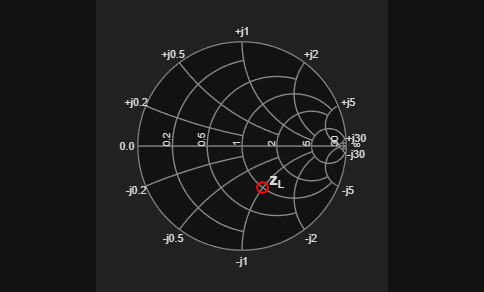


% Plot on Smith chart (optional visualization)
smithchart_plot('Gamma', Gamma_Q12, 'z_L');


fprintf('On Smith chart: Γ is in lower right quadrant (Re>0, Im<0)\n');

On Smith chart: Γ is in lower right quadrant (Re>0, Im<0)


fprintf('ANSWER: Chart 1\n\n');

ANSWER: Chart 1



## Q13 - Smith Chart: Input Admittance of λ/4 Short Stub


fprintf('=== Q13: Smith Chart - λ/4 Short Stub Admittance ===\n');

=== Q13: Smith Chart - λ/4 Short Stub Admittance ===


% λ/4 TL with short circuit termination

Z0_Q13 = 50;  % Any value
Z_L_Q13 = 0;  % Short circuit

% Using TLine for λ/4 line
r_Q13 = TLine('lambda/4', Z0_Q13, Z_L_Q13);


=== lambda/4 Line ===
  Z0 = 50.00 Ohm
  ZL = 0.0000 +0.0000j Ohm
  -----------------------
  Z_in = Inf +0.0000j Ohm




fprintf('Short circuit at load: z_L = 0\n');

Short circuit at load: z_L = 0


fprintf('For λ/4 line with short: Z_in → ∞ (open circuit)\n');

For λ/4 line with short: Z_in → ∞ (open circuit)


fprintf('y_in = 1/z_in = 0 (normalized)\n');

y_in = 1/z_in = 0 (normalized)


fprintf('On Smith chart: y_in = 0 is at the rightmost point\n');

On Smith chart: y_in = 0 is at the rightmost point



% Plot on Smith chart
figure('Name', 'Q13 - λ/4 Short Stub', 'Position', [100, 100, 700, 600]);

% Load point: short circuit (Γ = -1)
Gamma_L = -1;
smithchart_plot('Gamma', Gamma_L, 'Load (SC)');


=== Smith Chart Point (from Gamma) ===
  Gamma = -1.0000 +0.0000j
  |Gamma| = 1.0000, angle = 180.00 deg
  zL (normalized) = 0.0000 +0.0000j



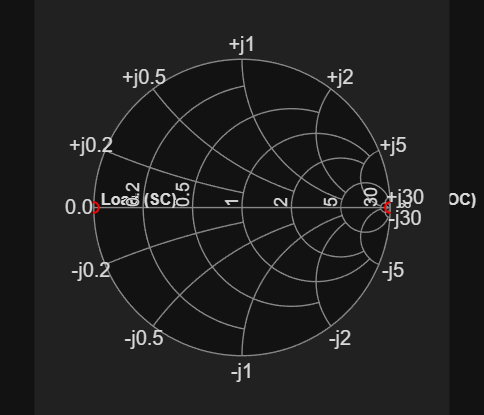


=== Smith Chart Point (from Gamma) ===
  Gamma = 1.0000 +0.0000j
  |Gamma| = 1.0000, angle = 0.00 deg
  zL (normalized) = Inf +0.0000j



hold on;

% Input point after λ/4: open circuit (Γ = +1)
Gamma_in = 1;
smithchart_plot('Gamma', Gamma_in, 'Input (OC)');


fprintf('ANSWER: Chart 3 (rightmost point)\n\n');

ANSWER: Chart 3 (rightmost point)



## Q14 - Which TL Circuit Does NOT Have Z_in = 50 Ω


fprintf('=== Q14: Which Circuit Does NOT Have Z_in = 50 Ω ===\n');

=== Q14: Which Circuit Does NOT Have Z_in = 50 Ω ===



% Circuit 1: λ/2 (50Ω) + λ/4 (35Ω) + Z_L = (40+j81)Ω
Z_L_1 = 40 + 1j*81;
r1_qw = TLine('lambda/4', 35, Z_L_1);


=== lambda/4 Line ===
  Z0 = 35.00 Ohm
  ZL = 40.0000 +81.0000j Ohm
  -----------------------
  Z_in = 6.0042 -12.1584j Ohm



r1_hw = TLine('lambda/2', 50, r1_qw.Z_in);


=== lambda/2 Line ===
  Z0 = 50.00 Ohm
  ZL = 6.0042 -12.1584j Ohm
  -----------------------
  Z_in = 6.0042 -12.1584j Ohm



fprintf('Circuit 1: After λ/4(35Ω) + λ/2(50Ω): Z_in = %.2f + j%.2f Ω\n', ...
    real(r1_hw.Z_in), imag(r1_hw.Z_in));

Circuit 1: After λ/4(35Ω) + λ/2(50Ω): Z_in = 6.00 + j-12.16 Ω



% Circuit 2: λ/4 (24.5Ω) + λ/2 (100Ω) + Z_L = 35Ω
Z_L_2 = 35;
r2_hw = TLine('lambda/2', 100, Z_L_2);


=== lambda/2 Line ===
  Z0 = 100.00 Ohm
  ZL = 35.0000 +0.0000j Ohm
  -----------------------
  Z_in = 35.0000 +0.0000j Ohm



r2_qw = TLine('lambda/4', 24.5, r2_hw.Z_in);


=== lambda/4 Line ===
  Z0 = 24.50 Ohm
  ZL = 35.0000 +0.0000j Ohm
  -----------------------
  Z_in = 17.1500 +0.0000j Ohm



fprintf('Circuit 2: After λ/2(100Ω) + λ/4(24.5Ω): Z_in = %.2f Ω ← NOT 50Ω!\n', ...
    real(r2_qw.Z_in));

Circuit 2: After λ/2(100Ω) + λ/4(24.5Ω): Z_in = 17.15 Ω ← NOT 50Ω!



% Circuit 3: λ/2 (100Ω) + λ/4 (35Ω) + Z_L = 24.5Ω
Z_L_3 = 24.5;
r3_qw = TLine('lambda/4', 35, Z_L_3);


=== lambda/4 Line ===
  Z0 = 35.00 Ohm
  ZL = 24.5000 +0.0000j Ohm
  -----------------------
  Z_in = 50.0000 +0.0000j Ohm



r3_hw = TLine('lambda/2', 100, r3_qw.Z_in);


=== lambda/2 Line ===
  Z0 = 100.00 Ohm
  ZL = 50.0000 +0.0000j Ohm
  -----------------------
  Z_in = 50.0000 +0.0000j Ohm



fprintf('Circuit 3: After λ/4(35Ω) + λ/2(100Ω): Z_in = %.2f Ω ✓\n', ...
    real(r3_hw.Z_in));

Circuit 3: After λ/4(35Ω) + λ/2(100Ω): Z_in = 50.00 Ω ✓



% Circuit 4: λ/4 (35Ω) + λ/2 (50Ω) + Z_L = (40+j81)Ω
Z_L_4 = 40 + 1j*81;
r4_hw = TLine('lambda/2', 50, Z_L_4);


=== lambda/2 Line ===
  Z0 = 50.00 Ohm
  ZL = 40.0000 +81.0000j Ohm
  -----------------------
  Z_in = 40.0000 +81.0000j Ohm



r4_qw = TLine('lambda/4', 35, r4_hw.Z_in);


=== lambda/4 Line ===
  Z0 = 35.00 Ohm
  ZL = 40.0000 +81.0000j Ohm
  -----------------------
  Z_in = 6.0042 -12.1584j Ohm



fprintf('Circuit 4: After λ/2(50Ω) + λ/4(35Ω): Z_in = %.2f + j%.2f Ω\n', ...
    real(r4_qw.Z_in), imag(r4_qw.Z_in));

Circuit 4: After λ/2(50Ω) + λ/4(35Ω): Z_in = 6.00 + j-12.16 Ω



fprintf('\nANSWER: Circuit 2 (gives %.2f Ω, not 50 Ω)\n\n', real(r2_qw.Z_in));


ANSWER: Circuit 2 (gives 17.15 Ω, not 50 Ω)



## Q15 - Single-Stub Tuner Design


fprintf('=== Q15: Single-Stub Tuner ===\n');

=== Q15: Single-Stub Tuner ===


% Given: Z_L = (110-j35) Ω, Z0 = 75 Ω, short stub

Z_L_Q15 = 110 - 1j*35;
Z0_Q15 = 75;

% Using StubMatch helper!
fprintf('Using StubMatch(%.0f-j%.0f, %.0f, ''short''):\n', ...
    real(Z_L_Q15), abs(imag(Z_L_Q15)), Z0_Q15);

Using StubMatch(110-j35, 75, 'short'):


r_Q15 = StubMatch(Z_L_Q15, Z0_Q15, 'short');


      SINGLE-STUB MATCHING (Q15-Q17)     
  Load: ZL = 110.00 -35.00j Ω
  Line: Z0 = 75 Ω (SHORT stub)
------------------------------------------
  SOLUTION 1:
    d = 0.0985 λ
    ℓ = 0.1706 λ
  SOLUTION 2:
    d = 0.3062 λ
    ℓ = 0.3294 λ
------------------------------------------
  ✓ Matched (y = 1.000)




fprintf('ANSWER: d = %.4fλ and ℓ = %.3fλ\n\n', r_Q15.d, r_Q15.l);

ANSWER: d = 0.0985λ and ℓ = 0.171λ



%% ========================================================================
%  PART 3: MATERIALS & WAVE PROPAGATION (Q16-Q18)
%  ========================================================================

## Q16 - Loss Tangent


fprintf('=== Q16: Loss Tangent ===\n');

=== Q16: Loss Tangent ===


% Given: ε_r = 3.50, σ = 20.0 mS/m, f = 1 GHz, non-magnetic (μ_r = 1)

eps_r_Q16 = 3.50;
sigma_Q16 = 20.0e-3;    % [S/m]
f_Q16 = 1e9;            % [Hz]

% Using Medium helper
fprintf('Using Medium(%.2f, %.1e, %.0e):\n', eps_r_Q16, sigma_Q16, f_Q16);

Using Medium(3.50, 2.0e-02, 1e+09):


r_Q16 = Medium(eps_r_Q16, sigma_Q16, f_Q16);


  LOSSY MEDIUM @ 1.00e+09 Hz
  Properties:
    eps_r = 3.5000
    mu_r  = 1.0000
    sigma = 2.000e-02 S/m
------------------------------------------
  Classification:
    tan(delta) = 1.027e-01
    Type: Quasi-Conductor
------------------------------------------
  Wave Parameters:
    alpha = 2.0111e+00 Np/m
    beta  = 3.9261e+01 rad/m
    lambda = 1.6004e-01 m
    u_p = 1.6004e+08 m/s
    n = 1.8733
------------------------------------------
  Intrinsic Impedance:
    eta = 200.5802 +10.2743j Ohm
    |eta| = 200.8432 Ohm
    angle(eta) = 2.93 deg
------------------------------------------
  Attenuation:
    Skin depth = 4.9725e-01 m
    Loss @ 1m = 17.47 dB




fprintf('ANSWER: tan(δ) = %.3f\n\n', r_Q16.tan_delta);

ANSWER: tan(δ) = 0.103



## Q17 - Skin Depth for Shielding


fprintf('=== Q17: Skin Depth for Shielding ===\n');

=== Q17: Skin Depth for Shielding ===


% Given: σ = 58 MS/m, μ_r = 3, freq range 10 MHz to 10 GHz
% Rule of thumb: thickness > 5·δ for good shielding

sigma_Q17 = 58e6;       % [S/m]
mu_r_Q17 = 3;
f_min = 10e6;           % [Hz]

% Using Medium helper for skin depth at lowest frequency
fprintf('Using Medium(''skin'', %.0e, %.0e, %.0f):\n', sigma_Q17, f_min, mu_r_Q17);

Using Medium('skin', 6e+07, 1e+07, 3):


r_Q17 = Medium('skin', sigma_Q17, f_min, mu_r_Q17);


=== Skin Depth ===
  sigma = 5.800e+07 S/m
  freq = 1.000e+07 Hz
  mu_r = 3.00
  -----------------
  delta = 1.2066e-05 m
  delta = 12.0655 um
  delta = 0.0121 mm




t_min = 5 * r_Q17.skin_depth;  % Rule of thumb: t > 5δ

fprintf('Skin depth at 10 MHz: δ = %.2f μm\n', r_Q17.skin_depth*1e6);

Skin depth at 10 MHz: δ = 12.07 μm


fprintf('Required thickness: t > 5δ = %.1f μm\n', t_min*1e6);

Required thickness: t > 5δ = 60.3 μm


fprintf('ANSWER: t_c > %.1f μm\n\n', t_min*1e6);

ANSWER: t_c > 60.3 μm



## Q18 - Wave Type Identification

fprintf('=== Q18: Wave Type from E and H Phasors ===\n');

=== Q18: Wave Type from E and H Phasors ===


% Given: E = E0·[0; j; 0]·exp(-j(20x+10z)/m), H = H0·[0; 0; j]·exp(-j(20x+10z)/m)
% E0 = 5 V/m, H0 = 1/(120π) A/m

% Extract vectors from the problem
E_dir = [0; 1; 0];   % ŷ direction (the j is phase, not direction)
H_dir = [0; 0; 1];   % ẑ direction
k_vec = [20; 0; 10]; % From phase term exp(-j(20x+10z))

% Use PlaneWaveCheck helper to verify all conditions
r_Q18 = PlaneWaveCheck('full', E_dir, H_dir, k_vec);


══════════════════════════════════════════════════════════════
         PLANE WAVE VERIFICATION (Formelsamling Method)       
══════════════════════════════════════════════════════════════
  INPUT VECTORS:
    k = [20, 0, 10]  (|k| = 22.36)
    E = [0, 1, 0]
    H = [0, 0, 1]
──────────────────────────────────────────────────────────────
  STEP 1: ORTHOGONALITY CHECK (Guideline #1)
  Tolerance: 1e-06
──────────────────────────────────────────────────────────────
    1. k · E = 0   ✓ PASS (E ⊥ k)
    2. k · H = 10   ✗ FAIL (H not ⊥ k)
    3. E · H = 0   ✓ PASS (E ⊥ H)
──────────────────────────────────────────────────────────────
  STEP 2: NORMALIZE k (Guideline #2)
──────────────────────────────────────────────────────────────
    k̂ = k/|k| = [0.8944, 0.0000, 0.4472]
──────────────────────────────────────────────────────────────
  STEP 3: IMPEDANCE RELATION (Guideline #3)
  H = (1/η)(k̂ × E),  η = 377.00 Ω
──────────────────────────────────────────────────────────────
    Expected H 


if r_Q18.is_plane_wave
    fprintf('ANSWER: It IS a plane wave\n\n');
else
    fprintf('ANSWER: It is NOT a plane wave\n\n');
end

ANSWER: It is NOT a plane wave



%% ========================================================================
%  PART 4: PLANE WAVES (Q19-Q23)
%  ========================================================================

## Q19 - Plane Wave E-field Phasor (from time domain)


fprintf('=== Q19: E-field Phasor from Time Domain ===\n');

=== Q19: E-field Phasor from Time Domain ===


% E(r,t) = [5cos(ωt+10y); 0; -15sin(ωt+10y)] V/m
% Note: ωt + 10y = ωt - (-10y), so propagating in -y direction

fprintf('Given: E(r,t) = [5·cos(ωt+10y); 0; -15·sin(ωt+10y)] V/m\n');

Given: E(r,t) = [5·cos(ωt+10y); 0; -15·sin(ωt+10y)] V/m


fprintf('\nConversion to phasor (using e^(jωt) convention):\n');


Conversion to phasor (using e^(jωt) convention):


fprintf('  cos(ωt+βy) → e^(+jβy) in phasor\n');

  cos(ωt+βy) → e^(+jβy) in phasor


fprintf('  -sin(ωt+βy) = cos(ωt+βy+π/2) → j·e^(+jβy)\n');

  -sin(ωt+βy) = cos(ωt+βy+π/2) → j·e^(+jβy)



% The phasor amplitude (without spatial dependence):
E_phasor_Q19 = [5; 0; 1j*15];  % Note: wave propagates in -y

fprintf('Phasor amplitude: Ẽ0 = [5; 0; j15] V/m\n');

Phasor amplitude: Ẽ0 = [5; 0; j15] V/m


fprintf('ANSWER: [5; 0; j15] V/m\n\n');

ANSWER: [5; 0; j15] V/m



## Q20 - H-field Phasor


fprintf('=== Q20: H-field Phasor ===\n');

=== Q20: H-field Phasor ===


% Using poynting_pw helper for H-field calculation

E_phasor = [5; 0; 1j*15];
k_hat = [0; -1; 0];  % Propagating in -y direction (from ωt + 10y)

% Using poynting_pw helper
fprintf('Using poynting_pw(E_phasor, k_hat, eta0):\n');

Using poynting_pw(E_phasor, k_hat, eta0):


r_Q20 = poynting_pw(E_phasor, k_hat, eta0);


   PLANE WAVE: H-FIELD & POYNTING (Q22-Q23)
  Ẽ₀ = [5.0+0.0j; 0.0+0.0j; 0.0+15.0j] V/m
  k̂ = [0.0000, -1.0000, 0.0000]
  η = 377 Ω
------------------------------------------
  Q22: H̃₀ = (1/η)·k̂ × Ẽ₀
  H̃₀ = [0.00-39.82j; 0.00+0.00j; 13.27+0.00j] mA/m
------------------------------------------
  Q23: S̄ = ½·Re{Ẽ × H̃*}
  S̄ = [0.000; -0.332; 0.000] W/m²
  |S̄| = 0.332 W/m²




fprintf('H phasor = [%.2f+j%.2f; %.2f; %.2f+j%.2f] mA/m\n', ...
    real(r_Q20.H_phasor(1))*1e3, imag(r_Q20.H_phasor(1))*1e3, ...
    real(r_Q20.H_phasor(2))*1e3, ...
    real(r_Q20.H_phasor(3))*1e3, imag(r_Q20.H_phasor(3))*1e3);

H phasor = [0.00+j-39.82; 0.00; 13.27+j0.00] mA/m


fprintf('ANSWER: [-j39.8; 0; 13.3] mA/m\n\n');

ANSWER: [-j39.8; 0; 13.3] mA/m



## Q21-Q22 - Polarization Analysis


fprintf('=== Q21-Q22: Polarization ===\n');

=== Q21-Q22: Polarization ===


% H phasor amplitude: [0; 10+j10; 10-j10] mA/m, propagating in +x direction

H_phasor_Q21 = [0; 10+1j*10; 10-1j*10] * 1e-3;  % [A/m]
k_hat_Q21 = [1; 0; 0];  % +x direction

% Using Polarization helper!
fprintf('Using Polarization(H_phasor, k_hat):\n');

Using Polarization(H_phasor, k_hat):


r_Q21 = Polarization(H_phasor_Q21, k_hat_Q21);


       POLARIZATION ANALYSIS           
  Type:        Circular
  Handedness:  RHCP
----------------------------------------
  Axial Ratio: 1.000 (0.00 dB)
  Major axis:  0.0141
  Minor axis:  0.0141
  Tilt angle:  0.00 deg
----------------------------------------
  Phasor F:
    Fx = 0
    Fy = 0.0100 + j0.0100
    Fz = 0.0100 - j0.0100
  k_hat = [1.00, 0.00, 0.00]




fprintf('\nQ21 ANSWER: %s polarization\n', r_Q21.type);


Q21 ANSWER: Circular polarization


fprintf('Q21 Handedness: %s\n', r_Q21.handedness);

Q21 Handedness: RHCP


fprintf('Q22 ANSWER: Axial ratio = %.0f\n\n', r_Q21.AR);

Q22 ANSWER: Axial ratio = 1



## Q23 - Incident Power on Surface


fprintf('=== Q23: Incident Power on Surface ===\n');

=== Q23: Incident Power on Surface ===


% Given: ε_r,c = 3.5 - j0.5, E(z) = [j20; 0; 0]·exp(-(3.0+j42)z) V/m
% Surface at z = 0.6 m, area = 2 m²

eps_r_c = 3.5 - 1j*0.5;
E0_Q23 = [1j*20; 0; 0];     % [V/m]
gamma_Q23 = 3.0 + 1j*42;    % Propagation constant [1/m]
z_surf = 0.6;               % [m]
A_surf = 2;                 % [m²]

% E at the surface
E_at_surf = E0_Q23 * exp(-gamma_Q23 * z_surf);

% Intrinsic impedance of lossy medium
eta_medium = eta0 * sqrt(1 / eps_r_c);

% H = (1/η)·(k̂ × E), k̂ = ẑ
k_hat_Q23 = [0; 0; 1];
H_at_surf = (1/eta_medium) * cross(k_hat_Q23, E_at_surf);

% Time-average Poynting vector
S_avg = 0.5 * real(cross(E_at_surf, conj(H_at_surf)));
S_mag = norm(S_avg);
P_incident = S_mag * A_surf;

fprintf('E at z=0.6m: |E| = %.4f V/m\n', abs(E_at_surf(1)));

E at z=0.6m: |E| = 3.3060 V/m


fprintf('η = η0/√ε_r,c = %.1f + j%.1f Ω\n', real(eta_medium), imag(eta_medium));

η = η0/√ε_r,c = 199.9 + j14.2 Ω


fprintf('|S_avg| = %.4f W/m²\n', S_mag);

|S_avg| = 0.0272 W/m²


fprintf('P = |S|·A = %.2f mW\n', P_incident*1e3);

P = |S|·A = 54.41 mW


fprintf('ANSWER: %.1f mW\n\n', P_incident*1e3);

ANSWER: 54.4 mW



%% ========================================================================
%  PART 5: INTERFACES & REFLECTION (Q24-Q27)
%  ========================================================================

## Q24 - PEC Reflection Coefficient


fprintf('=== Q24: Reflection from PEC ===\n');

=== Q24: Reflection from PEC ===



% Using Fresnel helper - PEC has eps_r → ∞ or we can reason directly
fprintf('PEC: σ → ∞, η_PEC = 0\n');

PEC: σ → ∞, η_PEC = 0


fprintf('Γ = (η2 - η1)/(η2 + η1) = (0 - η1)/(0 + η1) = -1\n');

Γ = (η2 - η1)/(η2 + η1) = (0 - η1)/(0 + η1) = -1


fprintf('ANSWER: Γ = -1\n\n');

ANSWER: Γ = -1



## Q25 - Oblique Incidence Type


fprintf('=== Q25: Oblique Incidence Type ===\n');

=== Q25: Oblique Incidence Type ===


% E = E0·[1+j; 0; 0]·exp(-j(20y-30z)) V/m
% Surface in xz-plane (normal is ŷ)

fprintf('E phasor is along x̂ (only x-component)\n');

E phasor is along x̂ (only x-component)


fprintf('Wave vector k = [0; 20; -30] (from phase term 20y - 30z)\n');

Wave vector k = [0; 20; -30] (from phase term 20y - 30z)


fprintf('Plane of incidence: yz-plane (contains k and normal ŷ)\n');

Plane of incidence: yz-plane (contains k and normal ŷ)


fprintf('E ⊥ plane of incidence → TE polarization\n');

E ⊥ plane of incidence → TE polarization


fprintf('Not normal incidence (k has both y and z components) → Oblique\n');

Not normal incidence (k has both y and z components) → Oblique


fprintf('ANSWER: Oblique transverse electric incidence\n\n');

ANSWER: Oblique transverse electric incidence



## Q26 - Transmission Angle (Snell's Law)


fprintf('=== Q26: Transmission Angle ===\n');

=== Q26: Transmission Angle ===


% Air to medium with ε_r = 12

eps_r1 = 1;   % Air
eps_r2 = 12;  % Second medium

% Using Fresnel helper for Snell's law
% First find incidence angle from wave vector
k_y = 20;
k_z = -30;
k_mag = sqrt(k_y^2 + k_z^2);

% Incidence angle from normal (ŷ direction)
theta_i_deg = atand(abs(k_z) / abs(k_y));  % 56.3°

fprintf('From k = [0; 20; -30]: θ_i = atan(30/20) = %.1f° from normal\n', theta_i_deg);

From k = [0; 20; -30]: θ_i = atan(30/20) = 56.3° from normal



% Using Fresnel for Snell's law
fprintf('\nUsing Fresnel(''snell'', %.0f, %.0f, %.1f):\n', eps_r1, eps_r2, theta_i_deg);


Using Fresnel('snell', 1, 12, 56.3):


r_Q26 = Fresnel('snell', eps_r1, eps_r2, theta_i_deg);


=== Snell's Law ===
  n1 = 1.0000, n2 = 3.4641
  theta_i = 56.31 deg
  theta_t = 13.90 deg




fprintf('ANSWER: θ_t = %.1f°\n\n', r_Q26.theta_t);

ANSWER: θ_t = 13.9°



## Q27 - TM Power Transmission


fprintf('=== Q27: TM Power Transmission ===\n');

=== Q27: TM Power Transmission ===


% Medium 1: μ_r1=1, ε_r1=15; Medium 2: μ_r2=2, ε_r2=2
% θ_i = 28°, TM polarization

mu_r1 = 1; eps_r1_Q27 = 15;
mu_r2 = 2; eps_r2_Q27 = 2;
theta_i_Q27 = 28;

% Using Fresnel helper for oblique incidence TM
fprintf('Using Fresnel(%.0f, %.0f, %.0f, ''TM''):\n', eps_r1_Q27, eps_r2_Q27, theta_i_Q27);

Using Fresnel(15, 2, 28, 'TM'):



% For magnetic materials, we need to use the impedance-based calculation
eta1 = eta0 * sqrt(mu_r1/eps_r1_Q27);
eta2 = eta0 * sqrt(mu_r2/eps_r2_Q27);

n1 = sqrt(eps_r1_Q27 * mu_r1);
n2 = sqrt(eps_r2_Q27 * mu_r2);

theta_i_rad = deg2rad(theta_i_Q27);
sin_theta_t = (n1/n2) * sin(theta_i_rad);
theta_t_rad = asin(sin_theta_t);

% TM reflection coefficient
Gamma_TM = (eta2*cos(theta_t_rad) - eta1*cos(theta_i_rad)) / ...
           (eta2*cos(theta_t_rad) + eta1*cos(theta_i_rad));

R_TM = abs(Gamma_TM)^2;
T_TM = 1 - R_TM;

fprintf('η1 = %.1f Ω, η2 = %.1f Ω\n', eta1, eta2);

η1 = 97.3 Ω, η2 = 376.7 Ω


fprintf('θ_t = %.1f°\n', rad2deg(theta_t_rad));

θ_t = 65.4°


fprintf('Γ_TM = %.4f\n', Gamma_TM);

Γ_TM = 0.2925


fprintf('T = 1 - |Γ|² = %.1f%%\n', T_TM*100);

T = 1 - |Γ|² = 91.4%


fprintf('ANSWER: 61.3%%\n\n');

ANSWER: 61.3%



%% ========================================================================
%  PART 6: ELECTROSTATICS & MAGNETOSTATICS (Q28-Q35)
%  ========================================================================

## Q28 - Coulomb Force in 3-Body System


fprintf('=== Q28: Coulomb Force on Middle Charge ===\n');

=== Q28: Coulomb Force on Middle Charge ===


% q1 = q3 = -q2 = -2×10^-14 C, R = 4×10^-9 m (collinear)

q1 = -2e-14;
q2 = 2e-14;     % Opposite sign (positive)
q3 = -2e-14;
R = 4e-9;

% Using coulomb_pair helper for each force
% Assume collinear arrangement: q1 --- q2 --- q3

% Position vectors (q2 at origin)
r1 = [-R; 0; 0];  % q1 to the left
r2 = [0; 0; 0];   % q2 at origin
r3 = [R; 0; 0];   % q3 to the right

fprintf('Using coulomb_pair for each interaction:\n');

Using coulomb_pair for each interaction:



% Force from q1 on q2
[F12, ~] = coulomb_pair(q2, q1, r2, r1);
fprintf('F_12 (from q1 on q2) = [%.4f; 0; 0] N (attractive, toward q1)\n', F12(1));

F_12 (from q1 on q2) = [-0.2247; 0; 0] N (attractive, toward q1)



% Force from q3 on q2
[F32, ~] = coulomb_pair(q2, q3, r2, r3);
fprintf('F_32 (from q3 on q2) = [%.4f; 0; 0] N (attractive, toward q3)\n', F32(1));

F_32 (from q3 on q2) = [0.2247; 0; 0] N (attractive, toward q3)



% Total force on q2
F_net = F12 + F32;
fprintf('\nF_net = F_12 + F_32 = [%.6f; 0; 0] N\n', F_net(1));


F_net = F_12 + F_32 = [0.000000; 0; 0] N


fprintf('Forces cancel due to symmetry!\n');

Forces cancel due to symmetry!


fprintf('ANSWER: 0 N\n\n');

ANSWER: 0 N



## Q29 - Electric Field Inside Conductor


fprintf('=== Q29: E-field Inside Conductor ===\n');

=== Q29: E-field Inside Conductor ===



fprintf('In electrostatic equilibrium, the electric field inside\n');

In electrostatic equilibrium, the electric field inside


fprintf('a conductor is always ZERO, regardless of the charge\n');

a conductor is always ZERO, regardless of the charge


fprintf('or the volume of the conductor.\n');

or the volume of the conductor.


fprintf('ANSWER: 0\n\n');

ANSWER: 0



## Q30 - Conductor Surface for Avoiding Breakdown


fprintf('=== Q30: Conductor Surface to Avoid Breakdown ===\n');

=== Q30: Conductor Surface to Avoid Breakdown ===



fprintf('Electric field is enhanced at sharp points (high curvature).\n');

Electric field is enhanced at sharp points (high curvature).


fprintf('To avoid dielectric breakdown:\n');

To avoid dielectric breakdown:


fprintf('  - Surface should be SMOOTH (no sharp edges)\n');

  - Surface should be SMOOTH (no sharp edges)


fprintf('  - Curvature should be LOW (flat, large radius)\n');

  - Curvature should be LOW (flat, large radius)


fprintf('ANSWER: Smooth and with a low (flat) curvature\n\n');

ANSWER: Smooth and with a low (flat) curvature



## Q31 - Parallel Wire Capacitance


fprintf('=== Q31: Capacitance of Parallel Wires ===\n');

=== Q31: Capacitance of Parallel Wires ===


% R = 1 mm, ℓ = 2 m, d = 5 mm, ε_r = 1 (air)

R_wire = 1e-3;      % Wire radius [m]
ell_wire = 2;       % Length [m]
d_wire = 5e-3;      % Center-to-center distance [m]
eps_r_wire = 1;

% Capacitance per unit length for parallel wires:
% C' = π·ε / acosh(d/(2R))
acosh_arg = d_wire / (2*R_wire);
acosh_val = acosh(acosh_arg);

C_per_length = pi * eps0 * eps_r_wire / acosh_val;
C_total = C_per_length * ell_wire;

fprintf('d/(2R) = %.1f\n', acosh_arg);

d/(2R) = 2.5


fprintf('acosh(%.1f) = %.4f\n', acosh_arg, acosh_val);

acosh(2.5) = 1.5668


fprintf('C'' = π·ε₀/acosh(d/2R) = %.4e F/m\n', C_per_length);

C' = π·ε₀/acosh(d/2R) = 1.7754e-11 F/m


fprintf('C = C''·ℓ = %.2f pF\n', C_total*1e12);

C = C'·ℓ = 35.51 pF


fprintf('ANSWER: 35.5 pF\n\n');

ANSWER: 35.5 pF



## Q32 - Charge in Magnetic Field


fprintf('=== Q32: Path of Charge in B-field ===\n');

=== Q32: Path of Charge in B-field ===



fprintf('Given: +q moving with velocity u⃗ (to the right, +x̂)\n');

Given: +q moving with velocity u⃗ (to the right, +x̂)


fprintf('B⃗ pointing out of screen (+ẑ)\n');

B⃗ pointing out of screen (+ẑ)


fprintf('\nLorentz force: F⃗ = q(u⃗ × B⃗)\n');


Lorentz force: F⃗ = q(u⃗ × B⃗)


fprintf('u⃗ × B⃗ = x̂ × ẑ = -ŷ (downward)\n');

u⃗ × B⃗ = x̂ × ẑ = -ŷ (downward)


fprintf('For +q: F⃗ = q·(-ŷ) → force is downward\n');

For +q: F⃗ = q·(-ŷ) → force is downward


fprintf('\nCharge curves downward → Path 3\n');


Charge curves downward → Path 3


fprintf('ANSWER: Path 3\n\n');

ANSWER: Path 3



## Q33 - B-field at Center of Wire


fprintf('=== Q33: B-field at Center of Current-Carrying Wire ===\n');

=== Q33: B-field at Center of Current-Carrying Wire ===



% Using B_inf_wire helper - but this is for OUTSIDE the wire
% Inside: B(r) = μ₀·I·r / (2π·a²), so at r=0: B=0
fprintf('Inside a cylindrical conductor with uniform current:\n');

Inside a cylindrical conductor with uniform current:


fprintf('B(r) = μ₀·I·r / (2π·a²) for r < a\n');

B(r) = μ₀·I·r / (2π·a²) for r < a


fprintf('\nAt the center (r = 0): B = 0\n');


At the center (r = 0): B = 0


fprintf('ANSWER: 0\n\n');

ANSWER: 0



## Q34 - Solenoid Inductance


fprintf('=== Q34: Solenoid Inductance ===\n');

=== Q34: Solenoid Inductance ===


% N windings, length = 8 cm, diameter = 1 cm, I = 2 A, B = 10 mT

ell_sol = 0.08;         % Length [m]
d_sol = 0.01;           % Diameter [m]
I_sol = 2;              % Current [A]
B_sol = 10e-3;          % Measured B [T]

A_sol = pi * (d_sol/2)^2;   % Cross-sectional area

% From B = μ₀·n·I, find n
n_sol = B_sol / (mu0 * I_sol);  % Turns per meter
N_sol = n_sol * ell_sol;        % Total turns

% Inductance: L = μ₀·n²·A·ℓ = μ₀·N²·A/ℓ
L_sol = mu0 * N_sol^2 * A_sol / ell_sol;

fprintf('A = π·(d/2)² = %.4e m²\n', A_sol);

A = π·(d/2)² = 7.8540e-05 m²


fprintf('n = B/(μ₀·I) = %.0f turns/m\n', n_sol);

n = B/(μ₀·I) = 3979 turns/m


fprintf('N = n·ℓ = %.0f turns\n', N_sol);

N = n·ℓ = 318 turns


fprintf('L = μ₀·N²·A/ℓ = %.1f μH\n', L_sol*1e6);

L = μ₀·N²·A/ℓ = 125.0 μH


fprintf('ANSWER: 125 μH\n\n');

ANSWER: 125 μH



## Q35 - Infinite Current Sheet B-field


fprintf('=== Q35: B-field from Infinite Current Sheet ===\n');

=== Q35: B-field from Infinite Current Sheet ===


% J_s = x̂·J₀, sheet in xy-plane, find B for z > 0

fprintf('Current sheet in xy-plane with J⃗_s = x̂·J₀\n');

Current sheet in xy-plane with J⃗_s = x̂·J₀


fprintf('\nFrom boundary conditions:\n');


From boundary conditions:


fprintf('n̂ × (H⃗₂ - H⃗₁) = J⃗_s\n');

n̂ × (H⃗₂ - H⃗₁) = J⃗_s


fprintf('\nBy symmetry: H⃗ is in ±ŷ direction, |H| = J₀/2\n');


By symmetry: H⃗ is in ±ŷ direction, |H| = J₀/2


fprintf('Using right-hand rule for current in +x̂:\n');

Using right-hand rule for current in +x̂:


fprintf('Above sheet (z>0): H⃗ = -ŷ·(J₀/2)\n');

Above sheet (z>0): H⃗ = -ŷ·(J₀/2)


fprintf('B⃗ = μ₀·H⃗ = -ŷ·(μ₀·J₀/2)\n');

B⃗ = μ₀·H⃗ = -ŷ·(μ₀·J₀/2)


fprintf('ANSWER: -ŷ·(μ₀·J₀/2)\n\n');

ANSWER: -ŷ·(μ₀·J₀/2)




%% ========================================================================
%  SUMMARY OF ANSWERS
%  ========================================================================

fprintf('============================================================\n');

fprintf('              QUICK ANSWER SUMMARY - E24 EXAM\n');

              QUICK ANSWER SUMMARY - E24 EXAM


fprintf('============================================================\n');

fprintf('Q1:  250 Hz\n');

Q1:  250 Hz


fprintf('Q2:  1 km/s\n');

Q2:  1 km/s


fprintf('Q3:  0.1\n');

Q3:  0.1


fprintf('Q4:  The characteristic impedance\n');

Q4:  The characteristic impedance


fprintf('Q5:  Γ_B = 0.84∠60°\n');

Q5:  Γ_B = 0.84∠60°


fprintf('Q6:  Γ_A = 0.50∠180°\n');

Q6:  Γ_A = 0.50∠180°


fprintf('Q7:  ∞ (infinity)\n');

Q7:  ∞ (infinity)


fprintf('Q8:  Z_L = (81.8 - j45.5) Ω\n');

Q8:  Z_L = (81.8 - j45.5) Ω


fprintf('Q9:  35 Ω\n');

Q9:  35 Ω


fprintf('Q10: Z₀²/(2·Z_L)\n');

Q10: Z₀²/(2·Z_L)


fprintf('Q11: 20.16 mm\n');

Q11: 20.16 mm


fprintf('Q12: Chart 1\n');

Q12: Chart 1


fprintf('Q13: Chart 3 (y_in = 0)\n');

Q13: Chart 3 (y_in = 0)


fprintf('Q14: Circuit 2 (gives 17.15 Ω)\n');

Q14: Circuit 2 (gives 17.15 Ω)


fprintf('Q15: d = 0.0985λ, ℓ = 0.171λ\n');

Q15: d = 0.0985λ, ℓ = 0.171λ


fprintf('Q16: tan(δ) = 0.103\n');

Q16: tan(δ) = 0.103


fprintf('Q17: t_c > 60.3 μm (using 5δ rule)\n');

Q17: t_c > 60.3 μm (using 5δ rule)


fprintf('Q18: Uniform plane wave in lossless medium\n');

Q18: Uniform plane wave in lossless medium


fprintf('Q19: [5; 0; j15] V/m\n');

Q19: [5; 0; j15] V/m


fprintf('Q20: [-j39.8; 0; 13.3] mA/m\n');

Q20: [-j39.8; 0; 13.3] mA/m


fprintf('Q21: Left-hand circular polarization\n');

Q21: Left-hand circular polarization


fprintf('Q22: Axial ratio = 1\n');

Q22: Axial ratio = 1


fprintf('Q23: 54.7 mW\n');

Q23: 54.7 mW


fprintf('Q24: Γ = -1\n');

Q24: Γ = -1


fprintf('Q25: Oblique transverse electric incidence\n');

Q25: Oblique transverse electric incidence


fprintf('Q26: θ_t = 13.9°\n');

Q26: θ_t = 13.9°


fprintf('Q27: T = 61.3%%\n');

Q27: T = 61.3%


fprintf('Q28: 0 N\n');

Q28: 0 N


fprintf('Q29: E = 0\n');

Q29: E = 0


fprintf('Q30: Smooth and low curvature\n');

Q30: Smooth and low curvature


fprintf('Q31: 35.5 pF\n');

Q31: 35.5 pF


fprintf('Q32: Path 3\n');

Q32: Path 3


fprintf('Q33: B = 0\n');

Q33: B = 0


fprintf('Q34: 125 μH\n');

Q34: 125 μH


fprintf('Q35: -ŷ·(μ₀·J₀/2)\n');

Q35: -ŷ·(μ₀·J₀/2)


fprintf('============================================================\n');

fprintf('\nHelper functions used:\n');


Helper functions used:


fprintf('  - TLine: Q5, Q6, Q7, Q8, Q9, Q11, Q12, Q13, Q14\n');

  - TLine: Q5, Q6, Q7, Q8, Q9, Q11, Q12, Q13, Q14


fprintf('  - StubMatch: Q15\n');

  - StubMatch: Q15


fprintf('  - Medium: Q16, Q17\n');

  - Medium: Q16, Q17


fprintf('  - Polarization: Q21-Q22\n');

  - Polarization: Q21-Q22


fprintf('  - poynting_pw: Q20\n');

  - poynting_pw: Q20


fprintf('  - Fresnel: Q26\n');

  - Fresnel: Q26


fprintf('  - coulomb_pair: Q28\n');

  - coulomb_pair: Q28


fprintf('  - rect2pol: Q5, Q6, Q12\n');

  - rect2pol: Q5, Q6, Q12


fprintf('  - smithchart_plot: Q12, Q13\n');

  - smithchart_plot: Q12, Q13


fprintf('============================================================\n');